# 5.3. Перенос энергии

#### Мощность продольной упругой волны

syms W(t) xi(x,t) F Y A 
diff(W(t),t)==-F*diff(xi(x,t),t)==-Y*A*diff(xi,x)*diff(xi,t)

$$ans(x, t) = \left(\frac{\partial }{\partial t}W\left(t\right)=-F\,\frac{\partial }{\partial t}\xi \left(x,t\right)\right)=-A\,Y\,\frac{\partial }{\partial t}\xi \left(x,t\right)\,\frac{\partial }{\partial x}\xi \left(x,t\right)$$

Символы взяты из раздела 5.1

В частности, плотность энергии и интенсивность гармонической волны

syms xi xi0 k x omega t
xi==xi0*sin(k*x-omega*t)

$$ans = \xi =\xi_{0}\,\sin\left(k\,x-\omega \,t\right)$$


$$\left\langle w\right\rangle =\frac{1}{2}\rho {\;\omega }^2 \;\xi_0^2$$


syms w rho omega avrg(x)
% avrg(w) = <w>
avrg(w)==1/2*rho*omega^2*xi0^2

$$ans = \mathrm{avrg}\left(w\right)=\frac{\omega^{2}\,\rho \,{\xi_{0}}^{2}}{2}$$

% I=<dW/dr>/A=c*<w>
syms I W(r) A c w
I==avrg(diff(W,r))/A==c*avrg(w)

$$ans = \left(\text{I}=\frac{\mathrm{avrg}\left(\frac{\partial }{\partial r}W\left(r\right)\right)}{A}\right)=c\,\mathrm{avrg}\left(w\right)$$

*Пример.* Гармоническая волна сжатия


$$\left\langle w\right\rangle =\frac{P_0^2 }{2\;c^2 \rho_0 }$$


syms w avrg(x) P0 c rho0 I 
avrg(w)==P0^2/(2*c^2*rho0)

$$ans = \mathrm{avrg}\left(w\right)=\frac{{P_{0}}^{2}}{2\,c^{2}\,\rho_{0}}$$

I==P0^2/(2*c*rho0)

$$ans = \text{I}=\frac{{P_{0}}^{2}}{2\,c\,\rho_{0}}$$

% P0 = амплитуда, см. в разделе 5.1

#### Акустическая интенсивность в децибелах

syms B I I0 lg(x)
B==10*lg(I/I0)

$$ans = B=10\,\mathrm{lg}\left(\frac{\text{I}}{I_{0}}\right)$$

% I0=1e-12 Вт*м-2

Интенсивность сферической гармонической волны сжатия

syms p p0 P0 r k r omega t w avrg(x)
p-p0==P0/r*sin(k*r-omega*t)

$$ans = p-p_{0}=\frac{P_{0}\,\sin\left(k\,r-\omega \,t\right)}{r}$$

I==c*avrg(w)==P0^2/(2*c*rho0*r^2)==I0/r^2

$$ans = \left(\left(\text{I}=c\,\mathrm{avrg}\left(w\right)\right)=\frac{{P_{0}}^{2}}{2\,c\,r^{2}\,\rho_{0}}\right)=\frac{I_{0}}{r^{2}}$$

% (r берется безразмерным)

#### Мощность поперечной волны

syms W(t) F_y xi(t)
diff(W,t)==F_y*diff(xi,t)

$$ans(t) = \frac{\partial }{\partial t}W\left(t\right)=F_{y}\,\frac{\partial }{\partial t}\xi \left(t\right)$$

% Символы взяты из раздела 5.1

#### Плоские электромагнитные волны

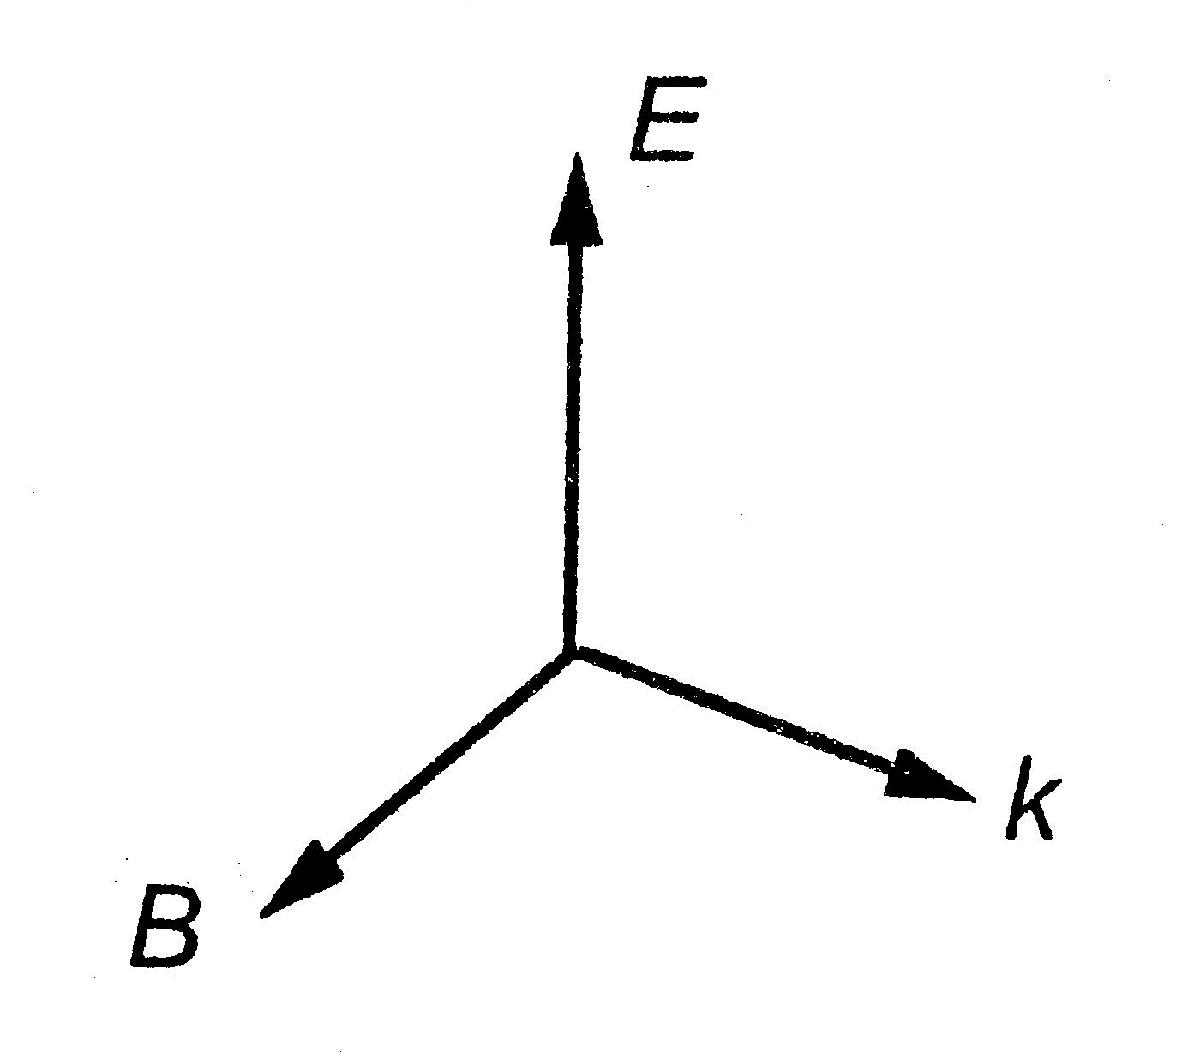

clear
syms E c B
E==c*B

$$ans = \text{E}=B\,c$$

Мгновенные плотности энергии и плотность потока излучения в вакууме

syms w_E epsilon0 E w_B mu0 B w I c0 w avrg(x)
% avrg(w) = <w>
w_E==1/2*epsilon0*E^2

$$ans = w_{E}=\frac{{\text{E}}^{2}\,\epsilon_{0}}{2}$$

w_B==1/(2*mu0)*B^2

$$ans = w_{B}=\frac{B^{2}}{2\,\mu_{0}}$$

w==w_E+w_B==epsilon0*E^2

$$ans = \left(w=w_{B}+w_{E}\right)={\text{E}}^{2}\,\epsilon_{0}$$

I==c0*avrg(w)

$$ans = \text{I}=c_{0}\,\mathrm{avrg}\left(w\right)$$

В частности, плоская гармоническая волна в вакууме

syms E E0 k x omega t I c0 wa c0 epsilon0 
E==E0*sin(k*x-omega*t)

$$ans = \text{E}=E_{0}\,\sin\left(k\,x-\omega \,t\right)$$

I==c0*avrg(w)==1/2*c0*epsilon0*E0^2

$$ans = \left(\text{I}=c_{0}\,\mathrm{avrg}\left(w\right)\right)=\frac{{E_{0}}^{2}\,c_{0}\,\epsilon_{0}}{2}$$

Плотность потока излучения плоской гармонической волны в диэлектрической среде с показателем преломления n

syms n epsilon
I==c0*avrg(w)==1/2*c0*epsilon*epsilon0*E0==1/2*n*c0*epsilon0*E0^2

$$ans = \left(\left(\text{I}=c_{0}\,\mathrm{avrg}\left(w\right)\right)=\frac{E_{0}\,c_{0}\,\epsilon \,\epsilon_{0}}{2}\right)=\frac{{E_{0}}^{2}\,c_{0}\,\epsilon_{0}\,n}{2}$$

Вектор Пойтинга


$$\mathit{\mathbf{S}}=\mathit{\mathbf{E}}\times \mathit{\mathbf{H}}$$


syms S E H vprod(x,y) mu mu0 B avrg(x)
S==vprod(E,H)

$$ans = S=\mathrm{vprod}\left(\text{E},H\right)$$

avrg(abs(S))==I

$$ans = \mathrm{avrg}\left(\left|S\right|\right)=\text{I}$$


$$\mathit{\mathbf{H}}=\frac{1}{\mu \;\mu_0 }\mathit{\mathbf{B}}$$


H==1/(mu*mu0)*B  % напряженность намагничевающего поля

$$ans = H=\frac{B}{\mu \,\mu_{0}}$$

Импульс и угловой момент на единицу объема в вакууме


$$\mathit{\mathbf{p}}=\varepsilon_0 \;\mathit{\mathbf{E}}\times \mathit{\mathbf{B}}$$


syms p epsilon0 E B vprod(x,y) L rcrossp r p w avrg(x) c0
p==epsilon0*vprod(E,B)

$$ans = p=\epsilon_{0}\,\mathrm{vprod}\left(\text{E},B\right)$$


$$\mathit{\mathbf{L}}=\mathit{\mathbf{r}}\times \mathit{\mathbf{p}}$$


L == vprod(r,p)

$$ans = L=\mathrm{vprod}\left(r,p\right)$$


$$\left\langle p\right\rangle =\frac{\left\langle w\right\rangle }{c_0 }=\frac{1}{c_0^2 }$$


avrg(p)==avrg(w)/c0==1/c0^2

$$ans = \left(\mathrm{avrg}\left(p\right)=\frac{\mathrm{avrg}\left(w\right)}{c_{0}}\right)=\frac{1}{{c_{0}}^{2}}$$

#### Давление излучения

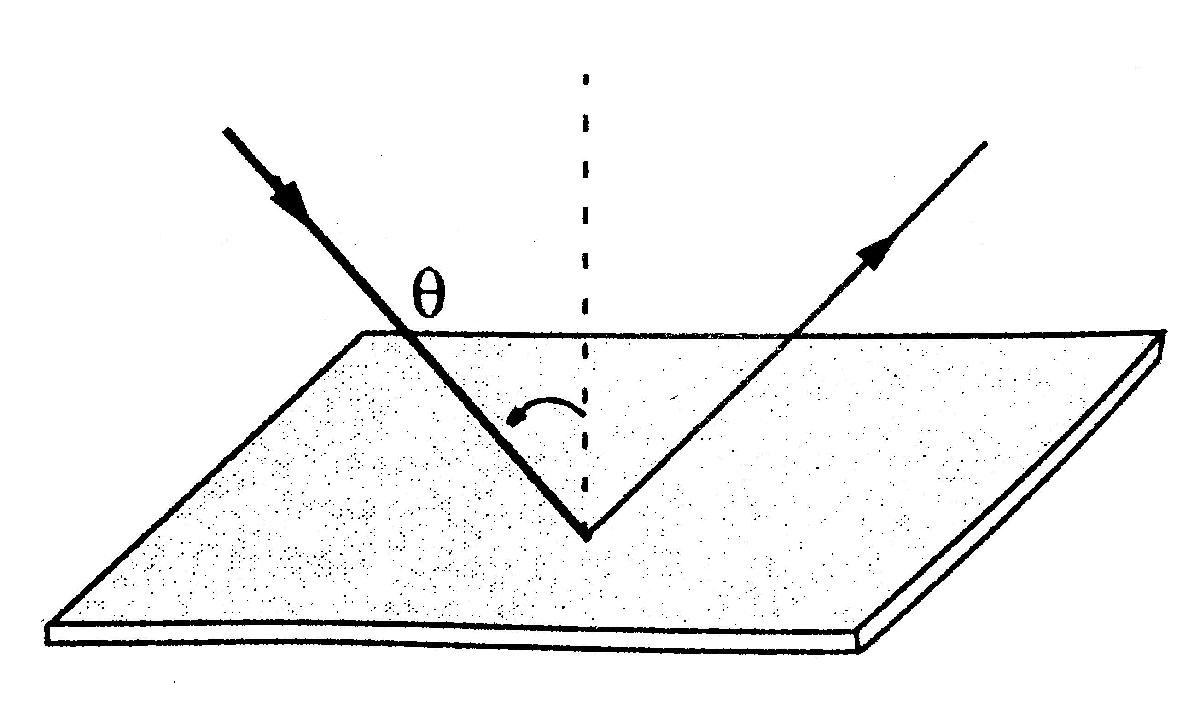

clear
syms P_s c p theta
P_s==c*p*cos(theta)^2   % при полном поглощении

$$ans = P_{s}=c\,p\,{\cos\left(\theta \right)}^{2}$$

P_s==2*c*p*cos(theta)^2  % при полном отражении

$$ans = P_{s}=2\,c\,p\,{\cos\left(\theta \right)}^{2}$$

P_s==1/3*p*c    % при полном изотропном поглощении

$$ans = P_{s}=\frac{c\,p}{3}$$

% Для частиц
syms p N m v V c
p==N*m*v/V, c==v

$$ans = p=\frac{N\,m\,v}{V}$$

$$ans = c=v$$

% N/V = число молекул массы m и скорости v в единице объема

#### Излучение движущегося с ускорением заряда Q (v<<c0)

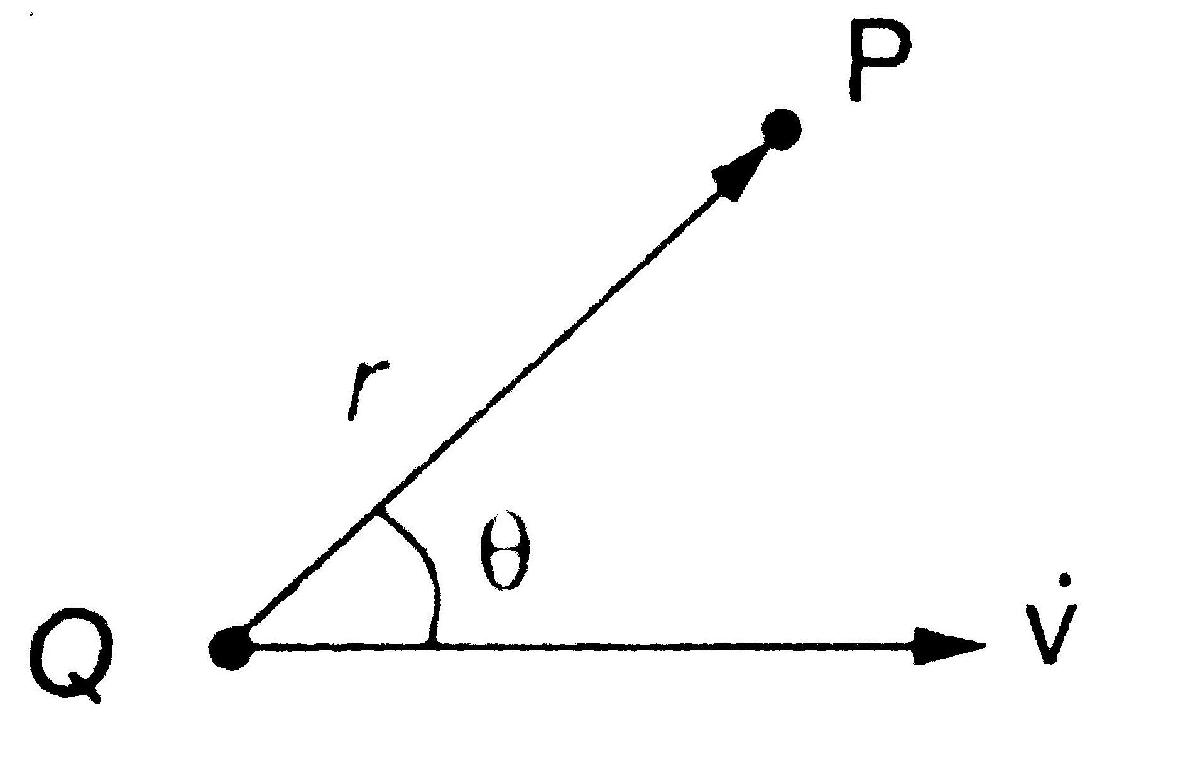

syms S mu0 Q vd theta c0 r W(t) epsilon0 avrg(x)
% vd = vdot = dv/dt
abs(S)==mu0*Q^2*vd^2*sin(theta)^2/(sym(16)*sym(pi)^2*c0*r^2)

$$ans = \left|S\right|=\frac{Q^{2}\,\mu_{0}\,{\mathrm{vd}}^{2}\,{\sin\left(\theta \right)}^{2}}{16\,c_{0}\,r^{2}\,\pi^{2}}$$

diff(W,t)==mu0*Q^2*vd^2/(6*pi*c0)==Q^2*vd^2/(6*pi*epsilon0*c0^3)

$$ans(t) = \left(\frac{\partial }{\partial t}W\left(t\right)=\frac{Q^{2}\,\mu_{0}\,{\mathrm{vd}}^{2}}{6\,c_{0}\,\pi }\right)=\frac{Q^{2}\,{\mathrm{vd}}^{2}}{6\,{c_{0}}^{3}\,\epsilon_{0}\,\pi }$$

#### Плотность потока излучения и полная мощность излучения от осциллирующего электрического диполя Q*z0*sin(omega*t)

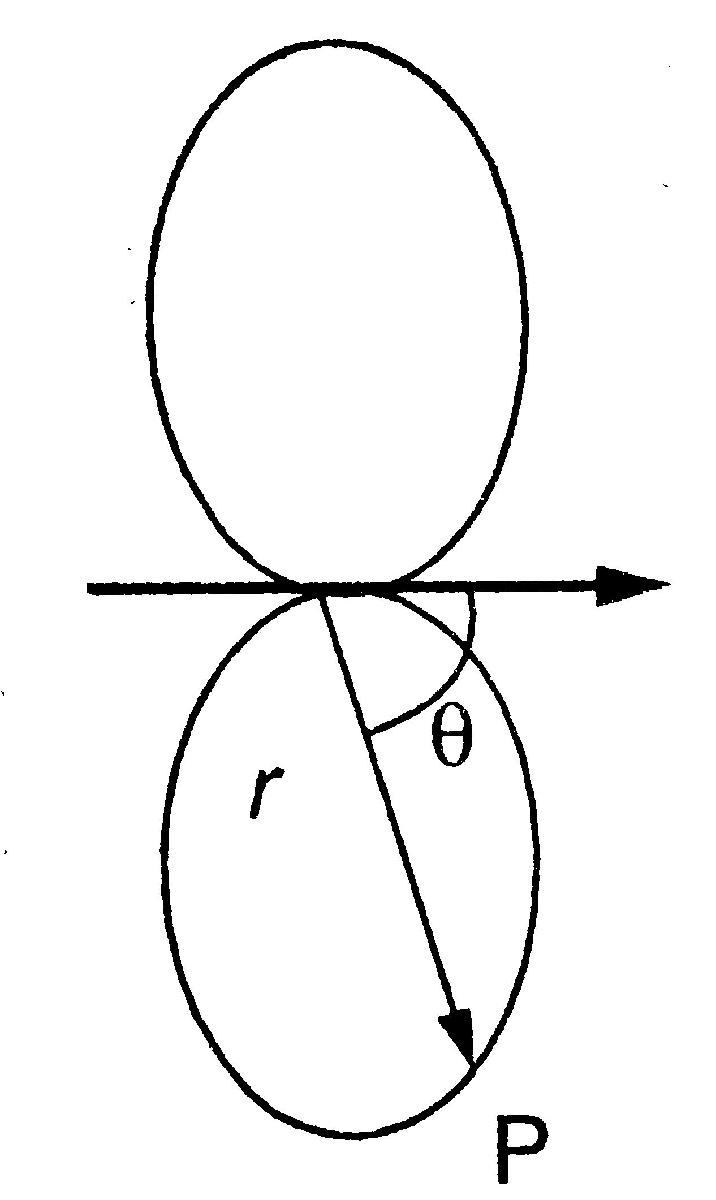

syms I mu0 Q z0 omega theta c0 r avrg(x)
I==mu0*Q^2*z0^2*omega^4*sin(theta)^2/(sym(32)*sym(pi)^2*c0*r^2)

$$ans = \text{I}=\frac{Q^{2}\,\mu_{0}\,\omega^{4}\,{z_{0}}^{2}\,{\sin\left(\theta \right)}^{2}}{32\,c_{0}\,r^{2}\,\pi^{2}}$$

avrg(diff(W,t))==mu0*Q^2*z0^2*omega^4/(12*pi*c0)

$$ans = \mathrm{avrg}\left(\frac{\partial }{\partial t}W\left(t\right)\right)=\frac{Q^{2}\,\mu_{0}\,\omega^{4}\,{z_{0}}^{2}}{12\,c_{0}\,\pi }$$

#### Полная мощность излучения электронного синхротрона или накопительного кольца

syms P I E R B 
P==vpa(88.5)*I*E^4/R==vpa(26.5)*I*B*E^3

$$ans = \left(P=\frac{88.5\,{\text{E}}^{4}\,\text{I}}{R}\right)=26.5\,B\,{\text{E}}^{3}\,\text{I}$$

% P = мощность (Вт)
% I = ток электронов (мА)
% E = энергия электронов (ГэВ)
% R = радиус орбиты электрона (м)
% B = плотность магнитного потока в отклоняющем магните (Тл)

#### Характеристическая длина волны, характеристическая частота и характеристическая энергия фотона для синхротронного излучения

syms lambda_c v_c epsilon_c R E B
lambda_c==vpa(0.56)*R/E^3==vpa(1.86)/(B*E^2)

$$ans = \left(\lambda_{c}=\frac{0.56\,R}{{\text{E}}^{3}}\right)=\frac{1.86}{B\,{\text{E}}^{2}}$$

v_c==vpa(540)*E^3/R==vpa(162)*B*E^2

$$ans = \left(v_{c}=\frac{540.0\,{\text{E}}^{3}}{R}\right)=162.0\,B\,{\text{E}}^{2}$$

epsilon_c==vpa(2.2)*E^3/R==vpa(0.67)*B*E^2

$$ans = \left(\epsilon_{c}=\frac{2.2\,{\text{E}}^{3}}{R}\right)=0.67\,B\,{\text{E}}^{2}$$

% lambda_c (нм)
% v_c (ПГц)
% epsilon_c  (кэВ)
% E (ГэВ)
% R (м)
% B (Тл)

#### Спектральная кривая синхротронного излучения